# Mini project - full pipeline

The goal of this session is to illustrate the entire pipeline for a project. We will be using the Urban Sound 8K [dataset](https://urbansounddataset.weebly.com/urbansound8k.html) consisting of a corpus of ordinary sounds recorded from day-to-day  city life. The data contains ten different categories such as drilling, dogs  barking, and sirens. The goal of the project is classification.

## Understanding the raw data

- Data structure: cf. "UrbanSound8K_README.txt"

- metadata: cf. "metadata/UrbanSound8K.csv"

- A numeric identifier of the sound class: 0 = air_conditioner; 1 = car_horn; 2 = children_playing; 3 = dog_bark; 4 = drilling; 5 = engine_idling; 6 = gun_shot; 7 = jackhammer; 8 = siren; 9 = street_music; 

- raw data: e.g. "fold1/7061-6-0-0.wav" => "[fsID]-[classID]-[occurrenceID]-[sliceID].wav"

## Getting the raw data in Matlab

datapath = "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS"; % change this for your own
mypath = fullfile(datapath, "UrbanSound8K");

### Using the metadatafile

We can load up the metadata file to get an overview:

meta = readtable(fullfile(mypath,"metadata/UrbanSound8K.csv"))

meta = 8732×8 table
       slice_file_name           fsID       start      xEnd      salience    fold    classID           class        
    ______________________    __________    ______    _______    ________    ____    _______    ____________________

    {'100032-3-0-0.wav'  }    1.0003e+05         0    0.31755       1          5        3       {'dog_bark'        }
    {'100263-2-0-117.wav'}    1.0026e+05      58.5       62.5       1          5        2       {'children_playing'}
    {'100263-2-0-121.wav'}    1.0026e+05      60.5       64.5       1          5        2       {'children_playing'}
    {'100263-2-0-126.wav'}    1.0026e+05        63         67       1          5        2       {'children_playing'}
    {

head(meta)

ans = 8×8 table
       slice_file_name           fsID       start     xEnd      salience    fold    classID           class        
    ______________________    __________    _____    _______    ________    ____    _______    ____________________

    {'100032-3-0-0.wav'  }    1.0003e+05       0     0.31755       1         5         3       {'dog_bark'        }
    {'100263-2-0-117.wav'}    1.0026e+05    58.5        62.5       1         5         2       {'children_playing'}
    {'100263-2-0-121.wav'}    1.0026e+05    60.5        64.5       1         5         2       {'children_playing'}
    {'100263-2-0-126.wav'}    1.0026e+05      63          67       1         5         2       {'children_playing'}
    {'100263-2-

This does not allow us to load up the raw files yet, so we build a new table with that allows us to do this (combine the pathnames and discrete class labels)

globalpath = rowfun( @(fname, fsid, start, xend, salience, fold, classid, class) fullfile(mypath, sprintf("fold%i",fold), fname), meta)

globalpath = 8732×1 table
                                                      Var1                                                  
    ________________________________________________________________________________________________________

    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100032-3-0-0.wav"  
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-117.wav"
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-121.wav"
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-126.wav"
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-137.wav"
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-143.wav"
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/

data = table(globalpath{:,1}, meta{:,"class"});
data.Properties.VariableNames = {'path','label'};
data.label = categorical(data.label, unique(data.label));
head(data)

ans = 8×2 table
                                                      path                                                           label      
    ________________________________________________________________________________________________________    ________________

    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100032-3-0-0.wav"      dog_bark        
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-117.wav"    children_playing
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-121.wav"    children_playing
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-126.wav"    children_playing
    "/Users/bart/Documents/Stack/DS425/Practical sessions/DS425-PS/PS/UrbanSound8K/fold5/100263-2-0-137.wav"    children_playing
    "/Users/

### Using the data folder(s)

Another option would be to use a datastore. We are working with sound files (stored as .wav) who do not have their type specific datastore, so we will need to build it ourselves:

mydatastore = fileDatastore(fullfile(mypath,"audio/"), "ReadFcn",@audioparser, "IncludeSubfolders",true,"FileExtensions",{'.wav'});

We now have the training data (or at least the path to each sound file). Think about why would we want to work in this way?

## Data exploration & parsing a single file 

Note that the file may appear similar when looking at them in the file explorer, but they are very different if we look more in detail:

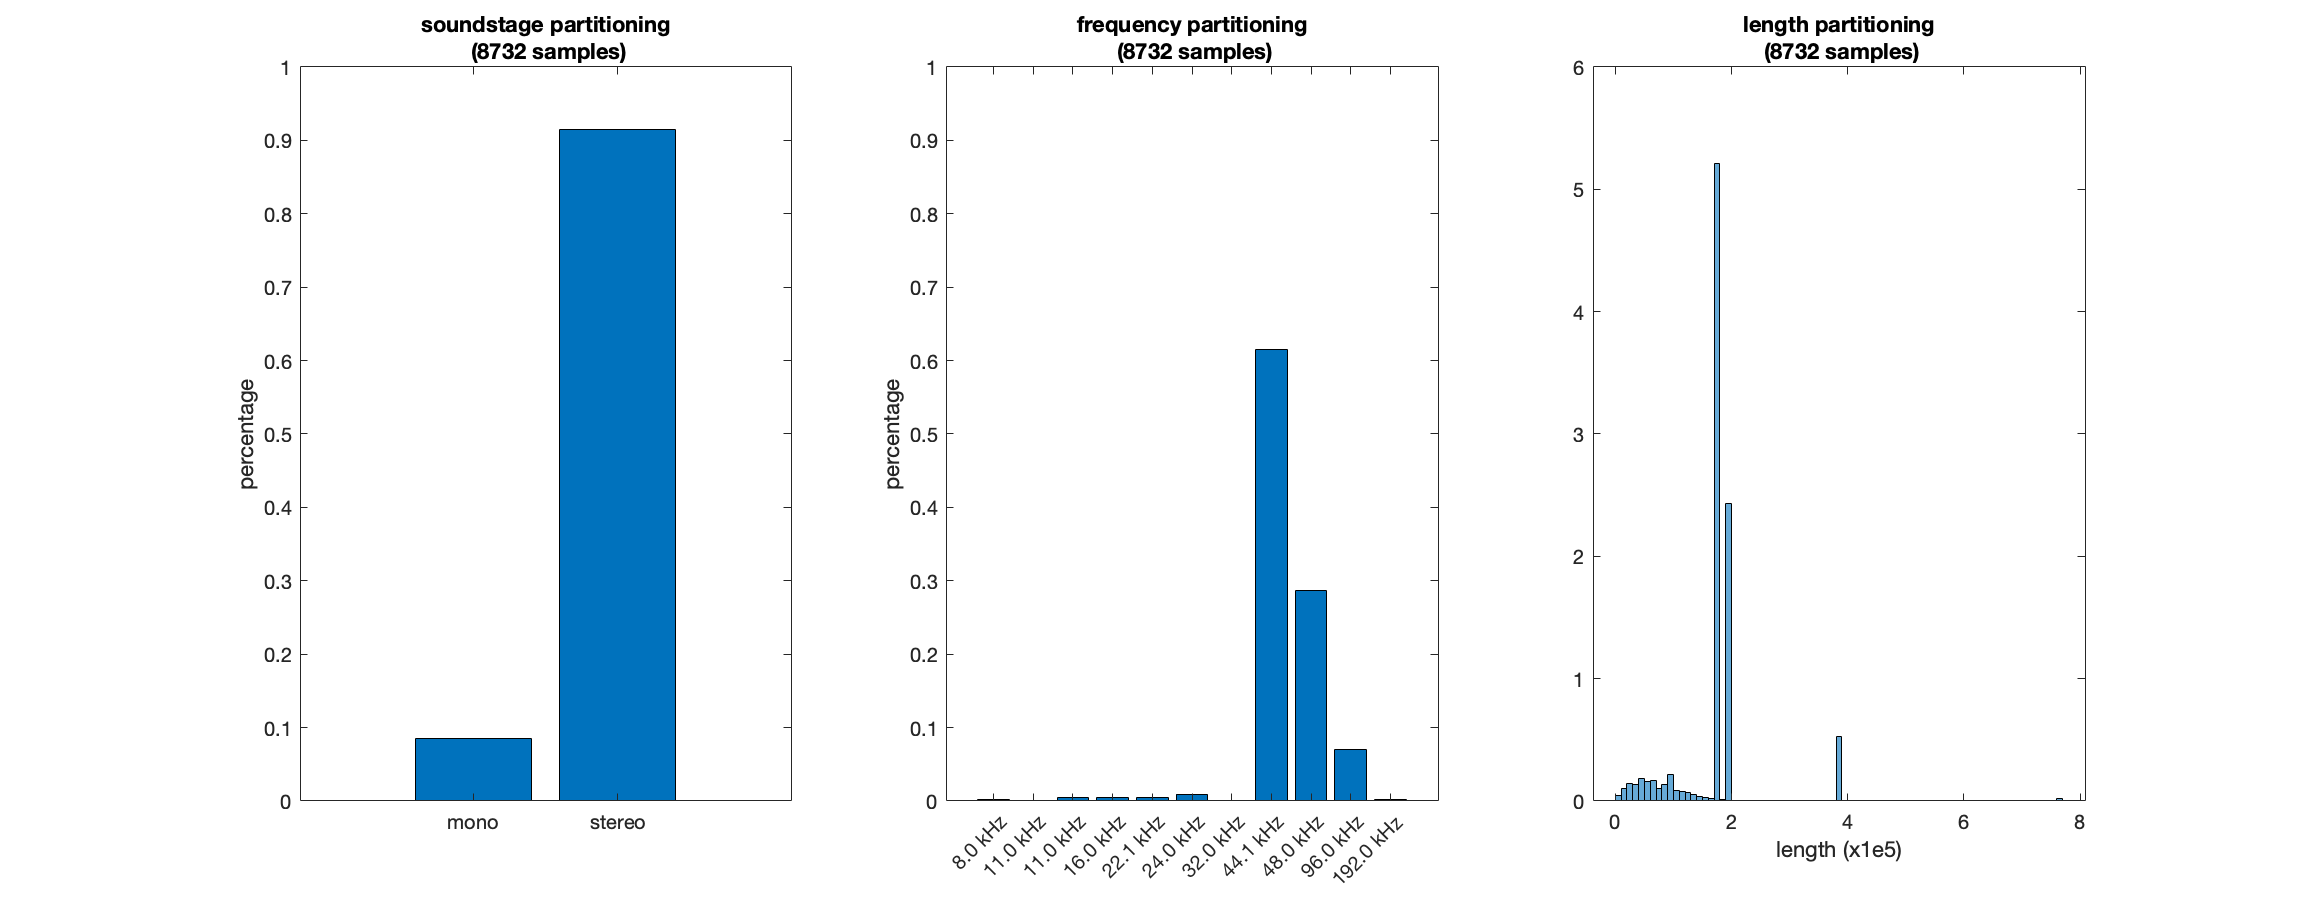

analysefiles(mydatastore,10000);

We can look at the different distributions and observe the following:

    => The majority of the data is in stereo 

    => The majority of the data is sampled at 44.1 kHz

    => The length of the sample varies

This shows that our data is heterogeneous. Before we can use this data in a ML pipeline, we need to make sure data our data is suited. This will required some operations:

- convert each sample to stereo (we could also do mono, but this would lead to information loss)

- up- or downsample each sample to the majority sampling rate

- pad or truncate each sample to the same length 

#### Single file parsing

Now we know some raw preprocessing that needs to be done and we see how we will parse a single file. We will first build up the pipeline and then integrate it in a larger function that integrates with the datastore and the entire ML pipeline. The effects of the raw preprocessing are shown below:

id = 5; % 1 5 100
myfile = mydatastore.Files{id};
y = audioparser(myfile, 'forcestereo', false, 'resample', false, 'fixlength', false, 'spectrogram', false);
size(y)

ans =       115101           2


y = audioparser(myfile, 'forcestereo', true, 'resample', false, 'fixlength', false, 'spectrogram', false);
size(y)

ans =       115101           2


y = audioparser(myfile, 'forcestereo', true, 'resample', true, 'samplefreq', 44100, 'fixlength', false, 'spectrogram', false);
size(y)

ans =       115101           2


y = audioparser(myfile, 'forcestereo', true, 'resample', true, 'samplefreq', 44100, 'fixlength', true,'duration',2, 'spectrogram', false);
size(y)

ans =        88200           2


y = audioparser(myfile, 'forcestereo', true, 'resample', true, 'fixlength', true,'duration',3,'samplefreq',32000, 'spectrogram', false);
size(y)

ans =        96000           2


After the previous steps we have a common base with which we can work. We use the `melSpectrogram `to generate different features (this is the part where some subject specific research on your specific topic comes in handy (take a look at "Preprocess Data for Domain-Specific Deep Learning Applications")

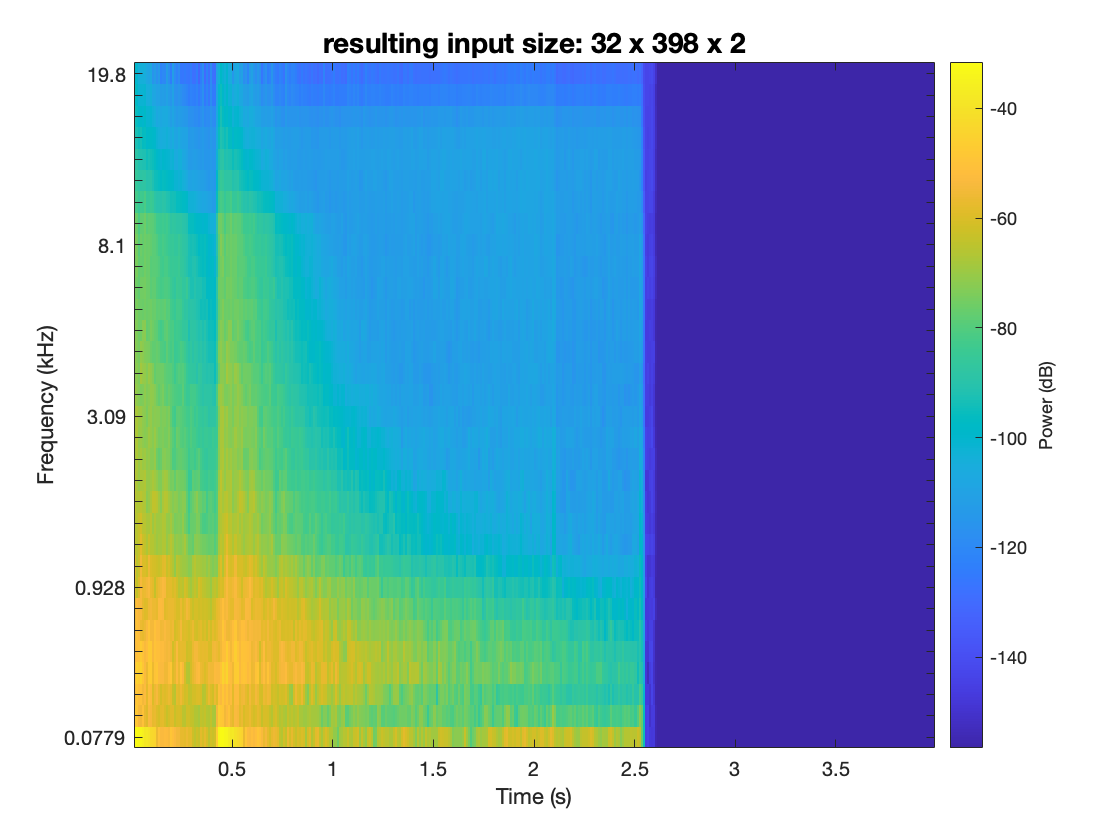

y = audioparser(myfile, 'spectrogram', false);
figure
melSpectrogram(y,44100);
title(sprintf('resulting input size: %i x %i x %i',size(melSpectrogram(y,44100),1),size(melSpectrogram(y,44100),2),size(melSpectrogram(y,44100),3)), 'FontSize',14)

We now have tranfsormed our sound file to an image with two channels (left and right from the stereo sound).

### Build a deep learning network

#### Input data

We need both the processed audio file as well as the file label. We obtain this by combining our different datastores (same path, different preprocessor)

mylabelstore = fileDatastore(fullfile(mypath,"audio/"), "ReadFcn", @labelparser, "IncludeSubfolders",true,"FileExtensions",{'.wav'});
% list of all the files found (notice this is identical to the table we used.
combinedstore = combine(mydatastore, mylabelstore)
preview(combinedstore)

### Network layout

layers = [imageInputLayer(size(y),"Name","sound inputlayer"),...
            convolution2dLayer([5 5],8,"Stride",[2 2],"Name","first convolution"),...
            reluLayer("Name","first relu"),...

combinedstore =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.FileDatastore]  [1×1 matlab.io.datastore.FileDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


            batchNormalizationLayer("Name","first normalisationn"),...

ans = 1×2 cell array
    {32×398×2 double}    {[dog_bark]}


            convolution2dLayer([3 3],16,"Stride",[2 2],"Name","second convolution"),...
            reluLayer("Name","second relu"),...
            batchNormalizationLayer("Name","second normalisationn"),...
            convolution2dLayer([3 3],32,"Stride",[2 2],"Name","third convolution"),...
            reluLayer("Name","third relu"),...
            batchNormalizationLayer("Name","thrid normalisationn"),...
            fullyConnectedLayer(10,"Name","output"),...
            softmaxLayer("Name","softmax"),...
            classificationLayer("Name","classoutput")]

layers =   1×13 Layer array with layers:

     1   'sound inputlayer'        Image Input             32×398×2 images with 'zerocenter' normalization
     2   'first convolution'       Convolution             8 5×5 convolutions with stride [2  2] and padding [0  0  0  0]
     3   'first relu'              ReLU                    ReLU
     4   'first normalisationn'    Batch Normalization     Batch normalization
     5   'second convolution'      Convolution             16 3×3 convolutions with stride [2  2] and padding [0  0  0  0]
     6   'second relu'             ReLU                    ReLU
     7   'second normalisationn'   Batch Normalization     Batch normalization
     8   'third convolution'       Convolution             32 3×3 convolutions with stride [2  2] and padding [0  0  0  0]
     9   'third relu'              ReLU                    ReLU
    10   'thrid normalisationn'    Batch Normalization  

#### Training


reset(combinedstore)
valstore = partition(combinedstore, 10, 9);
options = trainingOptions('adam',"Plots","training-progress","MiniBatchSize",32,'Shuffle',"never","Verbose",true,"MaxEpochs",500,"ValidationData",valstore)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 500
                 MiniBatchSize: 32
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: [1×1 matlab.io.datastore.CombinedDatastore]
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'never'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: 

% subselection of data
ministore = partition(combinedstore, 10, 1)

ministore =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.FileDatastore]  [1×1 matlab.io.datastore.FileDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]




[net,info] = trainNetwork(combinedstore, layers, options)

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:59 |        0.00% |       11.34% |       2.3026 |       2.3024 |          0.0010 |


|       1 |          50 |       00:03:25 |        0.00% |       11.91% |       2.3129 |       2.2696 |          0.0010 |


|       1 |         100 |       00:05:35 |       43.75% |       10.88% |       2.1978 |       2.2611 |          0.0010 |


|       1 |         150 |       00:08:00 |       40.62% |        8.71% |       2.3384 |       2.2631 |          0.0010 |


|       1 |         200 |       00:10:39 |        0.00% |        8.71% |       2.2583 |       2.2624 |          0.0010 |


|       1 |         250 |       00:13:16 |        0.00% |       13.63% |       2.2189 |       2.2516 |          0.0010 |


|       2 |         300 |       00:15:51 |       25.00% |       11.91% |       2.2848 |       2.2534 |          0.0010 |


|       2 |         350 |       00:18:24 |        6.25% |       13.17% |       2.1576 |       2.2531 |          0.0010 |


|       2 |         400 |       00:20:45 |        9.38% |       12.60% |       2.2478 |       2.2552 |          0.0010 |


|       2 |         450 |       00:23:12 |        0.00% |        9.05% |       2.3201 |       2.2992 |          0.0010 |


|       2 |         500 |       00:25:30 |        0.00% |        9.05% |       2.2084 |       2.2564 |          0.0010 |


|       3 |         550 |       00:27:17 |        9.38% |       13.17% |       2.1306 |       2.2502 |          0.0010 |


|       3 |         600 |       00:29:07 |       21.88% |       13.17% |       2.1710 |       2.2510 |          0.0010 |


|       3 |         650 |       00:31:07 |        0.00% |       10.88% |       2.1919 |       2.2553 |          0.0010 |


|       3 |         700 |       00:33:07 |        0.00% |       11.34% |       2.1905 |       2.2589 |          0.0010 |


|       3 |         750 |       00:34:47 |        0.00% |       11.34% |       2.2318 |       2.2609 |          0.0010 |


|       3 |         800 |       00:36:38 |        0.00% |       13.63% |       2.2654 |       2.2501 |          0.0010 |


|       4 |         850 |       00:38:54 |        0.00% |       13.17% |       2.5802 |       2.2513 |          0.0010 |


|       4 |         900 |       00:40:43 |       31.25% |       13.17% |       2.1504 |       2.2514 |          0.0010 |


|       4 |         950 |       00:43:02 |       21.88% |       11.34% |       2.2773 |       2.2571 |          0.0010 |


|       4 |        1000 |       00:44:55 |        0.00% |       12.60% |       2.3180 |       2.2993 |          0.0010 |


|       4 |        1050 |       00:46:54 |        0.00% |        9.05% |       2.2135 |       2.2555 |          0.0010 |


|       5 |        1100 |       00:48:55 |        0.00% |       11.91% |       2.5075 |       2.2581 |          0.0010 |


|       5 |        1150 |       00:50:54 |        9.38% |       13.17% |       2.2509 |       2.2513 |          0.0010 |


|       5 |        1200 |       00:52:47 |        0.00% |       13.17% |       2.1918 |       2.2520 |          0.0010 |


|       5 |        1250 |       00:55:00 |        0.00% |       11.34% |       2.2866 |       2.2566 |          0.0010 |


|       5 |        1300 |       00:56:52 |        0.00% |        8.71% |       2.2211 |       2.2633 |          0.0010 |


|       5 |        1350 |       00:58:53 |       21.88% |       13.63% |       2.1717 |       2.2509 |          0.0010 |


|       6 |        1400 |       01:01:04 |        0.00% |       13.17% |       2.2201 |       2.2514 |          0.0010 |


|       6 |        1450 |       01:03:05 |        0.00% |       13.17% |       2.1768 |       2.2517 |          0.0010 |


|       6 |        1500 |       01:05:23 |        0.00% |       11.34% |       2.7918 |       2.2555 |          0.0010 |


|       6 |        1550 |       01:07:10 |       56.25% |       12.60% |       2.2469 |       2.2784 |          0.0010 |


|       6 |        1600 |       01:09:17 |        0.00% |        9.05% |       2.1745 |       2.2545 |          0.0010 |


|       7 |        1650 |       01:11:29 |       62.50% |       11.91% |       2.1724 |       2.2581 |          0.0010 |


|       7 |        1700 |       01:13:52 |        3.12% |       13.17% |       2.1574 |       2.2518 |          0.0010 |


|       7 |        1750 |       01:16:02 |        0.00% |       11.34% |       2.1811 |       2.2520 |          0.0010 |


|       7 |        1800 |       01:18:16 |        0.00% |       11.34% |       2.7457 |       2.2575 |          0.0010 |


|       7 |        1850 |       01:21:23 |        0.00% |        9.05% |       2.2128 |       2.2588 |          0.0010 |


|       7 |        1900 |       01:23:18 |        0.00% |       13.63% |       2.1756 |       2.2508 |          0.0010 |


|       8 |        1950 |       01:25:21 |       21.88% |       11.91% |       2.5517 |       2.2510 |          0.0010 |


|       8 |        2000 |       01:27:32 |        0.00% |       10.88% |       2.1768 |       2.2520 |          0.0010 |


|       8 |        2050 |       01:29:48 |        0.00% |       11.34% |       2.1930 |       2.2536 |          0.0010 |


|       8 |        2100 |       01:31:53 |        0.00% |       12.60% |       2.2512 |       2.2660 |          0.0010 |


|       8 |        2150 |       01:33:33 |        0.00% |       13.17% |       2.1876 |       2.2523 |          0.0010 |


|       9 |        2200 |       01:35:52 |        0.00% |       11.91% |       2.1775 |       2.2546 |          0.0010 |


|       9 |        2250 |       01:37:47 |        0.00% |       13.17% |       2.2566 |       2.2530 |          0.0010 |


|       9 |        2300 |       01:39:36 |        0.00% |       12.60% |       2.1789 |       2.2535 |          0.0010 |


|       9 |        2350 |       01:41:25 |        0.00% |       12.60% |       2.2337 |       2.2624 |          0.0010 |


|       9 |        2400 |       01:43:11 |      100.00% |        9.05% |       2.1542 |       2.2570 |          0.0010 |


|      10 |        2450 |       01:44:59 |        3.12% |       13.63% |       2.1897 |       2.2509 |          0.0010 |


|      10 |        2500 |       01:47:07 |        0.00% |       13.17% |       2.1998 |       2.2508 |          0.0010 |


|      10 |        2550 |       01:48:55 |        0.00% |       10.88% |       2.2288 |       2.2537 |          0.0010 |


|      10 |        2600 |       01:51:05 |       28.12% |       13.63% |       2.3336 |       2.2536 |          0.0010 |


|      10 |        2650 |       01:53:00 |        0.00% |        8.71% |       2.2797 |       2.2609 |          0.0010 |


|      10 |        2700 |       01:54:44 |        3.12% |       13.17% |       2.4784 |       2.2519 |          0.0010 |


|      11 |        2750 |       01:56:48 |        6.25% |       13.17% |       2.1744 |       2.2514 |          0.0010 |


|      11 |        2800 |       01:58:56 |        3.12% |       13.17% |       2.1819 |       2.2519 |          0.0010 |


|      11 |        2850 |       02:00:49 |        0.00% |       12.60% |       2.1457 |       2.2542 |          0.0010 |


|      11 |        2900 |       02:02:50 |        0.00% |       12.60% |       2.2878 |       2.2692 |          0.0010 |


|      11 |        2950 |       02:04:52 |       21.88% |        9.05% |       2.2378 |       2.2562 |          0.0010 |


|      12 |        3000 |       02:06:43 |        3.12% |       11.91% |       2.1612 |       2.2518 |          0.0010 |


|      12 |        3050 |       02:08:57 |        0.00% |       13.17% |       2.5047 |       2.2510 |          0.0010 |


|      12 |        3100 |       02:11:02 |       12.50% |       13.17% |       2.2717 |       2.2527 |          0.0010 |


|      12 |        3150 |       02:12:54 |       12.50% |       11.34% |       2.3804 |       2.2546 |          0.0010 |


|      12 |        3200 |       02:14:49 |        0.00% |       12.60% |       2.2159 |       2.2611 |          0.0010 |


|      12 |        3250 |       02:16:44 |        0.00% |       13.63% |       2.2341 |       2.2516 |          0.0010 |


|      13 |        3300 |       02:19:39 |        0.00% |       13.17% |       2.1837 |       2.2511 |          0.0010 |


|      13 |        3350 |       02:21:45 |        0.00% |       13.17% |       2.1922 |       2.2511 |          0.0010 |


|      13 |        3400 |       02:24:03 |        0.00% |       11.34% |       2.2808 |       2.2551 |          0.0010 |


|      13 |        3450 |       02:26:10 |        0.00% |       12.60% |       2.2414 |       2.2682 |          0.0010 |


|      13 |        3500 |       02:28:12 |        0.00% |        9.05% |       2.2011 |       2.2560 |          0.0010 |


|      14 |        3550 |       02:30:20 |        0.00% |       11.91% |       2.1434 |       2.2566 |          0.0010 |


|      14 |        3600 |       02:32:37 |        9.38% |       13.17% |       2.1782 |       2.2524 |          0.0010 |


|      14 |        3650 |       02:34:28 |        0.00% |       13.17% |       2.1885 |       2.2514 |          0.0010 |


|      14 |        3700 |       02:36:41 |        0.00% |       13.63% |       2.2554 |       2.2539 |          0.0010 |


|      14 |        3750 |       02:38:38 |        0.00% |       10.88% |       2.2563 |       2.2621 |          0.0010 |


|      14 |        3800 |       02:40:35 |       18.75% |       13.63% |       2.1676 |       2.2528 |          0.0010 |


|      15 |        3850 |       02:43:08 |        0.00% |       12.60% |       2.1679 |       2.2512 |          0.0010 |


|      15 |        3900 |       02:45:10 |        0.00% |       13.17% |       2.1574 |       2.2515 |          0.0010 |


|      15 |        3950 |       02:47:18 |        0.00% |       11.34% |       2.1789 |       2.2536 |          0.0010 |


|      15 |        4000 |       02:49:33 |       28.12% |       12.60% |       2.2543 |       2.2616 |          0.0010 |


|      15 |        4050 |       02:51:38 |        6.25% |       12.60% |       2.2132 |       2.2537 |          0.0010 |


|      16 |        4100 |       02:53:46 |        0.00% |       11.91% |       2.6665 |       2.2587 |          0.0010 |


|      16 |        4150 |       02:55:57 |        6.25% |       13.17% |       2.1859 |       2.2526 |          0.0010 |


|      16 |        4200 |       02:58:16 |        0.00% |       12.60% |       2.2555 |       2.2522 |          0.0010 |


|      16 |        4250 |       03:00:24 |       34.38% |       11.34% |       2.1745 |       2.2557 |          0.0010 |


|      16 |        4300 |       03:02:27 |        0.00% |        9.05% |       2.2074 |       2.2579 |          0.0010 |


|      16 |        4350 |       03:04:29 |        0.00% |       13.63% |       2.2912 |       2.2519 |          0.0010 |


|      17 |        4400 |       03:07:03 |        0.00% |       11.91% |       2.3325 |       2.2511 |          0.0010 |


|      17 |        4450 |       03:09:15 |        3.12% |       13.17% |       2.2951 |       2.2517 |          0.0010 |


|      17 |        4500 |       03:11:13 |        0.00% |       11.34% |       2.2704 |       2.2535 |          0.0010 |


|      17 |        4550 |       03:13:08 |        0.00% |       12.60% |       2.2605 |       2.2579 |          0.0010 |


|      17 |        4600 |       03:15:54 |        0.00% |       13.17% |       2.2068 |       2.2520 |          0.0010 |


|      18 |        4650 |       03:17:53 |        0.00% |       11.91% |       2.2636 |       2.2527 |          0.0010 |


|      18 |        4700 |       03:19:52 |       28.12% |       13.17% |       2.2767 |       2.2529 |          0.0010 |


|      18 |        4750 |       03:21:52 |        0.00% |       12.60% |       2.3601 |       2.2534 |          0.0010 |


|      18 |        4800 |       03:23:57 |        0.00% |       12.60% |       2.2792 |       2.2575 |          0.0010 |


|      18 |        4850 |       03:25:56 |        0.00% |        9.05% |       2.3149 |       2.2560 |          0.0010 |


|      19 |        4900 |       03:28:11 |        6.25% |       13.17% |       2.2307 |       2.2518 |          0.0010 |


|      19 |        4950 |       03:30:21 |       15.62% |       13.17% |       2.1973 |       2.2511 |          0.0010 |


|      19 |        5000 |       03:32:43 |        0.00% |       10.88% |       2.1859 |       2.2527 |          0.0010 |


|      19 |        5050 |       03:34:39 |       34.38% |       11.34% |       2.1949 |       2.2541 |          0.0010 |


|      19 |        5100 |       03:36:38 |        0.00% |       12.60% |       2.2732 |       2.2579 |          0.0010 |


|      19 |        5150 |       03:38:47 |        0.00% |       13.17% |       2.3949 |       2.2517 |          0.0010 |


|      20 |        5200 |       03:41:06 |       15.62% |       13.17% |       2.1646 |       2.2511 |          0.0010 |


|      20 |        5250 |       03:43:16 |        3.12% |       13.17% |       2.1718 |       2.2513 |          0.0010 |


|      20 |        5300 |       03:45:41 |        0.00% |       12.60% |       2.2302 |       2.2548 |          0.0010 |


|      20 |        5350 |       03:47:58 |        0.00% |       12.60% |       2.2844 |       2.2665 |          0.0010 |


|      20 |        5400 |       03:50:20 |        0.00% |        9.05% |       2.3111 |       2.2551 |          0.0010 |


|      21 |        5450 |       03:52:43 |       25.00% |       11.91% |       2.1904 |       2.2535 |          0.0010 |


|      21 |        5500 |       03:55:09 |        0.00% |       13.17% |       2.2051 |       2.2514 |          0.0010 |


|      21 |        5550 |       03:57:23 |        0.00% |       13.17% |       2.2966 |       2.2521 |          0.0010 |


|      21 |        5600 |       03:59:29 |       18.75% |       13.63% |       2.1923 |       2.2538 |          0.0010 |


|      21 |        5650 |       04:01:29 |        0.00% |        8.71% |       2.3108 |       2.2618 |          0.0010 |


|      21 |        5700 |       04:03:40 |        0.00% |       13.63% |       2.2365 |       2.2530 |          0.0010 |


|      22 |        5750 |       04:06:01 |        0.00% |       13.17% |       2.1881 |       2.2509 |          0.0010 |


|      22 |        5800 |       04:08:19 |        0.00% |       13.17% |       2.3717 |       2.2513 |          0.0010 |


|      22 |        5850 |       04:10:47 |        0.00% |       11.34% |       2.2151 |       2.2560 |          0.0010 |


|      22 |        5900 |       04:12:52 |        0.00% |       12.60% |       2.2788 |       2.2651 |          0.0010 |


|      22 |        5950 |       04:15:25 |       18.75% |       12.60% |       2.1853 |       2.2544 |          0.0010 |


|      23 |        6000 |       04:17:39 |        0.00% |       11.91% |       2.2118 |       2.2576 |          0.0010 |


|      23 |        6050 |       04:19:55 |        9.38% |       13.17% |       2.2305 |       2.2520 |          0.0010 |


|      23 |        6100 |       04:22:08 |        0.00% |       12.60% |       2.1629 |       2.2516 |          0.0010 |


|      23 |        6150 |       04:24:37 |        0.00% |       11.34% |       2.6717 |       2.2529 |          0.0010 |


|      23 |        6200 |       04:27:09 |        0.00% |       10.88% |       2.2005 |       2.2608 |          0.0010 |


|      23 |        6250 |       04:29:36 |       18.75% |       13.63% |       2.2013 |       2.2530 |          0.0010 |


|      24 |        6300 |       04:32:05 |        0.00% |       12.60% |       2.3558 |       2.2511 |          0.0010 |


|      24 |        6350 |       04:34:21 |       12.50% |       13.17% |       2.3755 |       2.2515 |          0.0010 |


|      24 |        6400 |       04:36:43 |      100.00% |       11.34% |       2.1444 |       2.2525 |          0.0010 |


|      24 |        6450 |       04:39:02 |        0.00% |       12.60% |       2.2585 |       2.2594 |          0.0010 |


|      24 |        6500 |       04:41:26 |        0.00% |       12.60% |       2.4992 |       2.2523 |          0.0010 |


|      25 |        6550 |       04:43:54 |        0.00% |       11.91% |       2.2640 |       2.2569 |          0.0010 |


|      25 |        6600 |       04:45:57 |        0.00% |       13.17% |       2.1701 |       2.2530 |          0.0010 |


|      25 |        6650 |       04:48:06 |       65.62% |       12.60% |       2.1473 |       2.2532 |          0.0010 |


|      25 |        6700 |       04:50:19 |       12.50% |       12.60% |       2.2005 |       2.2582 |          0.0010 |


|      25 |        6750 |       04:52:21 |        0.00% |        9.05% |       2.3107 |       2.2556 |          0.0010 |


|      25 |        6800 |       04:54:40 |        3.12% |       13.63% |       2.2064 |       2.2515 |          0.0010 |


|      26 |        6850 |       04:57:17 |        0.00% |       11.91% |       2.2322 |       2.2508 |          0.0010 |


|      26 |        6900 |       04:59:39 |       43.75% |       10.88% |       2.1633 |       2.2529 |          0.0010 |


|      26 |        6950 |       05:02:15 |        0.00% |       13.63% |       2.4682 |       2.2518 |          0.0010 |


|      26 |        7000 |       05:04:46 |       62.50% |        8.71% |       2.1958 |       2.2575 |          0.0010 |


|      26 |        7050 |       05:07:10 |        0.00% |       13.17% |       2.1978 |       2.2510 |          0.0010 |


|      27 |        7100 |       05:09:35 |       25.00% |       11.91% |       2.2991 |       2.2520 |          0.0010 |


|      27 |        7150 |       05:12:03 |        0.00% |       11.34% |       2.1616 |       2.2529 |          0.0010 |


|      27 |        7200 |       05:14:58 |        9.38% |       12.60% |       2.2260 |       2.2545 |          0.0010 |


|      27 |        7250 |       05:16:58 |        0.00% |        9.05% |       2.4533 |       2.2624 |          0.0010 |


|      27 |        7300 |       05:18:53 |        0.00% |        9.05% |       2.2225 |       2.2542 |          0.0010 |


|      28 |        7350 |       05:21:14 |        9.38% |       11.91% |       2.1496 |       2.2517 |          0.0010 |


|      28 |        7400 |       05:23:37 |       34.38% |       13.17% |       2.1696 |       2.2509 |          0.0010 |


|      28 |        7450 |       05:25:56 |       18.75% |       13.17% |       2.1720 |       2.2530 |          0.0010 |


|      28 |        7500 |       05:28:21 |        0.00% |       11.34% |       2.1704 |       2.2539 |          0.0010 |


|      28 |        7550 |       05:30:42 |        0.00% |        8.71% |       2.2217 |       2.2603 |          0.0010 |


|      28 |        7600 |       05:33:06 |        6.25% |       13.17% |       2.2570 |       2.2514 |          0.0010 |


|      29 |        7650 |       05:35:42 |        0.00% |       13.17% |       2.6114 |       2.2505 |          0.0010 |


|      29 |        7700 |       05:37:57 |       31.25% |       13.17% |       2.1522 |       2.2513 |          0.0010 |


|      29 |        7750 |       05:40:20 |       21.88% |       12.60% |       2.2742 |       2.2553 |          0.0010 |


|      29 |        7800 |       05:42:39 |        0.00% |       12.60% |       2.2449 |       2.2649 |          0.0010 |


|      29 |        7850 |       05:44:57 |        9.38% |       13.17% |       2.2174 |       2.2545 |          0.0010 |


|      30 |        7900 |       05:47:07 |        0.00% |       11.91% |       2.4614 |       2.2538 |          0.0010 |


|      30 |        7950 |       05:49:44 |        9.38% |       13.17% |       2.2436 |       2.2516 |          0.0010 |


|      30 |        8000 |       05:52:03 |        0.00% |       13.17% |       2.1827 |       2.2520 |          0.0010 |


|      30 |        8050 |       05:54:34 |        0.00% |       11.34% |       2.2569 |       2.2535 |          0.0010 |


|      30 |        8100 |       05:56:46 |        0.00% |        8.71% |       2.2249 |       2.2611 |          0.0010 |


|      30 |        8150 |       05:58:58 |       21.88% |       13.63% |       2.1645 |       2.2527 |          0.0010 |


|      31 |        8200 |       06:01:28 |        0.00% |       13.63% |       2.2177 |       2.2510 |          0.0010 |


|      31 |        8250 |       06:03:58 |        0.00% |       13.17% |       2.1812 |       2.2509 |          0.0010 |


|      31 |        8300 |       06:06:32 |        0.00% |       11.34% |       2.7673 |       2.2556 |          0.0010 |


|      31 |        8350 |       06:09:02 |        0.00% |       13.17% |       2.2041 |       2.2611 |          0.0010 |


|      31 |        8400 |       06:11:35 |        0.00% |       12.60% |       2.2018 |       2.2537 |          0.0010 |


|      32 |        8450 |       06:14:06 |       62.50% |       11.91% |       2.1840 |       2.2581 |          0.0010 |


|      32 |        8500 |       06:16:19 |        3.12% |       13.17% |       2.1584 |       2.2522 |          0.0010 |


|      32 |        8550 |       06:18:38 |       50.00% |       12.60% |       2.1772 |       2.2521 |          0.0010 |


|======================================================================================================================|


function [y] = audioparser(path,options)
%AUDIOPARSER parse single audio file for our ML pipeline
%   AUDIOPARSER(PATH) reads file at PATH. File will be converted to stereo
%   if its mono. All preprocessing for the ML pipeline happen here as well
%
%   Keywords:
%   - forcestereo: logical (default = true) 
%        transform signal to stereo
%   - resample: logical (default = true) 
%        resample the signal specified sampling frequency
%   - fixlength: logical (default = true) 
%        pad or truncate the sample to fixed duration in milliseconds
%   - samplefreq: double (default = 44100 [Hz])
%       resample frequency
%   - duration: double (default = 4 [ms])
%       duration of the sample, will be padded or truncated
%   - spectrogram: logical (default = true)
%       generate mel spectrogram from data
    arguments
        path
        options.forcestereo (1,1) logical = true
        options.resample (1,1) logical = true
        options.fixlength (1,1) logical = true
        options.samplefreq (1,1) double = 44100
        options.duration (1,1) double = 4
        options.spectrogram (1,1) logical = true
    end
    % load up the audio data
    [y,Fs] = audioread(path);
    
    % convert to stereo if required
    if options.forcestereo
        if size(y,2) == 1
            y = [y y];
        else
            y = y;
        end
    end
    
    % resample to majority sampling rate
    if options.resample
        if Fs ~= options.samplefreq
            y = resample(y,Fs, options.samplefreq);
            Fs = options.samplefreq;
        end
    end
    
    % pad or truncate if required
    if options.fixlength
        maxlength = Fs * options.duration;
        if size(y,1) > maxlength % truncate
            y = y(1:maxlength,:);
        elseif size(y,1) < maxlength % pad zeros (@start <> @end <> @random start location ?)
            y = [y;zeros(maxlength-size(y,1), size(y,2))];
        end
    end
    
    % obtain melSpectrogram
    if options.spectrogram
        y = melSpectrogram(y, Fs);
        % result in dB (not allowing NaN in case of zeros)
        y = log10(y );%+ 1e-12);
    end
    
end

function data = labelparser(path)
%LABELPARSER extract label for single audio file for our ML pipeline
%   LABELPARSER(PATH) reads file at PATH. Label is extracted from the
%   fileneme.
    label = split(path,"-");
    data = str2double(label(end-2));
    data= categorical(data, 0:9,  {'air_conditioner' 'car_horn' 'children_playing' 'dog_bark' 'drilling' 'engine_idling' 'gun_shot' 'jackhammer' 'siren' 'street_music'}); 
end

function analysefiles(store, N)
%ANALYSEFILESS show mono vs stereo files in datastore
%   ANALYSEFILES(STORE, N) reads first N audio file in the STORE and
%   makes a figure of:
%   - the repartition between mono and stereo. 
%   - the repartion of the sampling rates.
% 
% 
%   If N is larger than the size of the store it will be limited to the total
%   length of all files.
    mono = 0; stereo = 0; 
    freqs = containers.Map('KeyType','Int32','ValueType','double');
    N = min(length(store.Files), N);
    slen = zeros(N,1);
    for i = 1:N
        [y,FS] = audioread(store.Files{i});
        slen(i) = size(y,1);
        if size(y,2) == 1
            mono = mono+1;
        else
            stereo = stereo+1;
        end
        
        if isKey(freqs, FS)
            freqs(FS) = freqs(FS) + 1;
        else
            freqs(FS) = 1;
        end

    end
    h = figure();

    subplot(1,3,1)
    bar([1;2],[mono, stereo] ./ (mono + stereo))
    xticklabels(["mono";"stereo"]);
    ylim([0;1]);
    title(sprintf("soundstage partitioning\n (%i samples)",i))
    ylabel("percentage")
    
    subplot(1,3,2)
    bar(1:freqs.Count, cell2mat(freqs.values)/ sum(cell2mat(freqs.values)))
    xticklabels(cellfun(@(x) sprintf("%2.1f kHz",double(x(1))/1000), freqs.keys));
    xtickangle(45)
    ylim([0;1]);
    title(sprintf("frequency partitioning\n (%i samples)",i))
    ylabel("percentage")
    
    subplot(1,3,3)
    histogram(slen / 1e5,'Normalization',"pdf")
    title(sprintf("length partitioning\n (%i samples)",i))
    xlabel("length (x1e5)")
    
    set(h,'Units','normalized','Position',[0 0 0.8 .5]); 
end